addpath('Shapes')
addpath('Subfunctions')
%load("Data\CFD_confined_TSR_1_1.mat")
%load("Data\CFD_confined_LES_TSR_1_9.mat")
load("Data\TSR_1_9.mat")
X = flow_data(1).X;
Y = flow_data(1).Y;
theta = zeros(length(flow_data),1);
for i = 1:length(flow_data)
    theta(i) = flow_data(i).theta;
end
%thetab = flip(theta);
%test adjust
thetab = 365 - theta;
syms t;
Ry2 = [cosd(t) sind(t); -sind(t) cosd(t)];
thet = [0:pi/32:2*pi,0]';
rt = 2.042;
Uinf = 0.91;
lam = 1.1;
%lam = 1.9;
Omega = lam*Uinf/rt;
GC = struct;
GC.alphaP = 6;
GC.lambda = lam;
Urels = struct;
num = length(theta)

num = 62

Rqcs = [-1.65 -1.85 -2.05 -2.25 -2.45;0 0 0 0 0];
Rqcs = [Rqcs(1,:);Rqcs(2,:)+2.042];
dThetas = zeros(1,length(Rqcs),num);
rbvs = zeros(2,length(Rqcs),num);
bvs = zeros(2,1,num);
Us = struct;

tic
for k = 1:num%length(theta)
alpha = theta(k);
U = flow_data(k).u;
V = flow_data(k).v;
sz = length(X);
XY = [X(:) Y(:)];
% XYRy2 = XY*Ry2;
% res = subs(XYRy2,t,-alpha);
% res = double(res);
Rot = [cosd(-alpha) sind(-alpha); -sind(-alpha) cosd(-alpha)];
res = XY*Rot;
Xrot3 = reshape(res(:,1), size(X,1), []);
Yrot3 = reshape(res(:,2), size(Y,1), []);
foiltest = plot_foil(theta(k),1);
% XYRy2 = Ry2*foiltest';
% res = subs(XYRy2,t,alpha);
res = Rot*foiltest';
foiltest(:,:) = res';
%qc = 2.118*[sind(theta(k));cosd(theta(k))];
qc = 2.042*[sind(theta(k));cosd(theta(k))];
qc = Ry2*qc;
qc = subs(qc,t,-alpha);
qc = double(qc);

radius = [1.6 1.7 1.8 1.9 2]./2;
%radius = [1.6 1.7]./2;
sizes = [1 1.3 1.6 1.9 2.2];
Cin = zeros(length(X),length(X),length(radius));
Ca = zeros(66,2,length(radius));
for i = 1:length(radius)
    [Cin(:,:,i),Ca(:,:,i)] = Circle2(qc,radius(i),Xrot3,Yrot3);
end
Rin2 = zeros(length(X),length(X),length(Rqcs));
Ra2 = zeros(5,2,length(Rqcs));
for i = 1:length(Rqcs)
    [Rin2(:,:,i),Ra2(:,:,i)] = Rect2(Rqcs(:,i),0.1,2,Xrot3,Yrot3);
end

%[Pin, Pa] = Points(theta,1,1,rt,X,Y);
[Pin, Pa] = Points2(qc,1,0.5,Xrot3,Yrot3);
%need to investigate making a Points2.m to meet 
% standards of other methods. Points.m derives
% the quarter chord (qc) from inputs, may be 
% better to just give qc point.
%Also in need of investigation is the m and 
% n parameters of Points.m

%[Cin,Ca] = Circle2(qc,1,Xrot3,Yrot3);
qc(1) = qc(1)-1;
[Rin,Ra] = Rect2(qc,0.25,2,Xrot3,Yrot3);
foiltest2 = plot_foil(theta(k),1.5);
% XYRy2 = Ry2*foiltest2';
% res = subs(XYRy2,t,alpha);
res = Rot*foiltest2';
foiltest2(:,:) = res';
Bin = inpolygon(Xrot3,Yrot3,foiltest2(:,1),foiltest2(:,2));



UV = [U(:) V(:)];
% XYRy2 = UV*Ry2;
% res = subs(XYRy2,t,-alpha);
% res = double(res);
res = UV*Rot;
u3 = reshape(res(:,1), size(X,1), []);
v3 = reshape(res(:,2), size(Y,1), []);

rRef = hypot(XY(:,1),XY(:,2));
pv = Omega*rRef.*[-cosd(alpha),-sind(alpha)];
UV4 = [u3(:) v3(:)];
UV4 = UV4+pv;
u4 = reshape(UV4(:,1), size(X,1), []);
v4 = reshape(UV4(:,2), size(Y,1), []);

for i = 1:length(radius)
    Umeans.Circle(i) = mean(u4(logical(Cin(:,:,i))));
    Umeans.Rec(i) = mean(u4(logical(Rin2(:,:,i))));
end
Umeans.Point = mean(u4(logical(Pin)));
Vmeans.Point = mean(v4(logical(Pin)));
%this needs adjusting bc rn it averages both points 
% and I don't want to do that yet?


for i = 1:length(radius)
    Vmeans.Circle(i) = mean(v4(logical(Cin(:,:,i))));
    Vmeans.Rec(i) = mean(v4(logical(Rin2(:,:,i))));
end

rbv = Rqcs*0;
for i = 1:length(Rqcs)
    rRef = hypot(Rqcs(1,i),Rqcs(2,i));
    rbv(:,i) = Omega*rRef.*[-cosd(alpha);-sind(alpha)];
end

% for i = 1:2
%     rRefP = hypot(Pa(1,i),Pa(2,i));
%     pbv(:,i) = Omega*rRefP.*[-cosd(alpha);-sind(alpha)];
% end
%maybe if I separate out each pt but until then

rRefP = hypot(mean(Pa(1,:)),mean(Pa(2,:)));
pbv = Omega*rRefP.*[-cosd(alpha);-sind(alpha)];

rbvs(:,:,k) = rbv;

dThetas(:,:,k) = (Umeans.Rec(:,:)+rbv(1,:))./abs(Rqcs(1,:))*Omega;

bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
bvs(:,:,k) = bv;

Yrot4 = Yrot3-2.042;

% quiver(Xrot3,Yrot4,u4,v4)
% xlim([-2.5 1.5])
% ylim([-1.5 1.5])
% grid on
% hold on
% fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
% for i = 1:length(radius)
% quiver(0,0,Umeans.Circle(i)+bv(1),Vmeans.Circle(i)+bv(2),'LineWidth',2)
% end
% for i = 1:length(radius)
%     plot(Ca(:,1,i),Ca(:,2,i)-2.042)
% end
%plot(Ca(:,1),Ca(:,2))
%plot(Ra(:,1),Ra(:,2))
%plot(foiltest2(:,1),foiltest2(:,2),'k')
%hold off

%aoa testing
for i = 1:length(radius)
Urels(k).C(i,:) = [Umeans.Circle(i);Vmeans.Circle(i)]+bv;
Urels(k).R(i,:) = [Umeans.Rec(i);Vmeans.Rec(i)]+rbv(:,i);
end
Urels(k).P = [Umeans.Point;Vmeans.Point]+pbv;
Us(k).u3 = u3;
Us(k).v3 = v3;
Us(k).u4 = u4;
Us(k).v4 = v4;
end
toc

Elapsed time is 1.621289 seconds.


for k = 1:num
    alpha = theta(k);
    bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
    bvs(:,:,k) = bv;
end
bvs

% tic
% for b = 1:62
% for i = 1:length(radius)
% Urels(k).C(i,:) = [Umeans.Circle(i);Vmeans.Circle(i)]+bv;
% Urels(k).R(i,:) = [Umeans.Rec(i);Vmeans.Rec(i)]+rbv(:,i);
% end
% end
% toc

% banan = zeros(length(radius),2,k,2);
% tic
% for b = 1:62
% for i = 1:length(radius)
% banan(i,:,k,1) = [Umeans.Circle(i);Vmeans.Circle(i)]+bv;
% banan(i,:,k,2) = [Umeans.Rec(i);Vmeans.Rec(i)]+rbv(:,i);
% end
% end
% toc

test2 = [Umeans.Circle(1);Vmeans.Circle(1)]+bv
hypot(test2(1),test2(2))

addpath("Subfunctions")
AOA(-bv,Urels(1).C(1,:)',theta(1),GC)
alpha

% for i =1:length(theta)
%     
% end

%duder = zeros(length(theta),1)
duder = zeros(num,1)
for i =1:num%length(theta)
duder(i) = hypot(Urels(i).C(1),Urels(i).C(1,2))/Uinf;
end
plot(theta(1:num),duder)
hold on
duder3 = zeros(num,1);
for i =1:num%length(theta)
duder3(i) = hypot(Urels(i).R(1),Urels(i).R(1,2))/Uinf;
end
plot(theta(1:num),duder3)
hold off

duder5 = zeros(num,1);
for i =1:num%length(theta)
duder5(i) = hypot(Urels(i).P(1),Urels(i).P(2))/Uinf;
end
plot(theta(1:num),duder5)
hold on
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1))
hold off


for i =1:num
    dt(i) = dThetas(:,1,i);
end
plot(theta,dt)
hold on
for j =2:5
    for i =1:num
    dt(i) = dThetas(:,j,i);
    end
plot(theta,dt)
end
hold off

duder*Uinf^2

%duder2 = zeros(length(theta),1)
duder2 = zeros(num,1)
for i = 1:num%length(theta)
    [duder2(i,1),duder2(i,2)] = AOA(-bvs(:,:,i),Urels(i).C(4,:)',theta(i),GC);
end
plot(theta(1:num),duder2(:,2),theta(1:num),-duder2(:,1))
% don't forget if it throws an error, just try adding path

duder6 = zeros(num,1);
duder10 = duder6
for i = 1:num%length(theta)
    %rRefP = hypot(mean(Pa(1,:)),mean(Pa(2,:)));
    pbv = Omega*rRefP.*[-cosd(theta(i));-sind(theta(i))];
    [duder6(i,1),duder6(i,2)] = AOA(-pbv,Urels(i).P,theta(i),GC);
    duder10(i,1) = atand(-(Urels(i).P(2)+pbv(1))/(Urels(i).P(1)+pbv(1)))+GC.alphaP;
end
plot(theta(1:num),duder6(:,2),theta(1:num),-duder6(:,1),theta(1:num),duder10)
legend('nominal','point aoa')

duder10


atand(-(Urels(1).P(1)-pbv(1))/(Urels(1).P(2)-pbv(2)))+GC.alphaP
atand(-(Urels(1).P(2)+pbv(1))/(Urels(1).P(1)+pbv(1)))+GC.alphaP

duder7 = zeros(num,1);
duder11 = duder7;
for i = 1:num
    pbv = Omega*rRefP.*[-cosd(theta(i));-sind(theta(i))];
    duder7(i) = hypot(Urels(i).P(1)-pbv(1),Urels(i).P(2)-pbv(2))/Uinf;
    duder11(i) = norm([Omega*rt+Urels(i).P(1)-pbv(1),Urels(i).P(2)-pbv(2)])/Uinf;
end
plot(theta(1:num),duder7)
hold on
plot(theta(1:num),duder5)
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1))
%plot(theta(1:num),duder11)
hold off
legend('new','old','nominal')

pbvs1 = zeros(num,2);
RelU = zeros(num,1);
RelV = RelU;
for i = 1:num
pbvs1(i,:) = Omega*rRefP.*[-cosd(theta(i));-sind(theta(i))];
RelU(i) = Urels(i).P(1);
RelV(i) = Urels(i).P(2);
end
plot(theta(1:num),pbvs1)
plot(theta(1:num),RelU)
plot(theta(1:num),RelV)
plot(theta(1:num),hypot(RelU,RelV))

hypot(Urels(num).P(1),Urels(num).P(2))/Uinf

% making some figs for owen
Xrot5 = zeros(sz);
Yrot5 = zeros(sz);
h = 32
alp = theta(h);
for j = 1:sz
    T3 = [X(:,1)';Y(:,j)'];
    XYRy2 = Ry2*T3; 
    res = subs(XYRy2,t,alp);
    Xrot5(:,j) = res(1,:);
    Yrot5(:,j) = res(2,:);
end
Yrot6 = Yrot5 - 2.042;

[Pin3,Pa3] = Points2([0;2.042],0.5,1,Xrot5,Yrot5);
[Cin3, Ca3] = Circle2([0;2.042],0.8,Xrot5,Yrot5);
rRefP = hypot(mean(Pa3(1,:)),mean(Pa3(2,:)));
pbv = Omega*rRefP.*[-cosd(alp);-sind(alp)];

for k = 1:num
    alpha = theta(k);
    bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
    bvs(:,:,k) = bv;
end

quiver(Xrot5,Yrot6,Us(h).u4,Us(h).v4)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
hold on
fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
%quiver(0,0,Urels(h).P(1)-bvs(1,:,h),Urels(h).P(2)-bvs(2,:,h))
quiver(0,0,mean(Us(h).u3(logical(Pin3)))+bvs(1,:,h),mean(Us(h).v3(logical(Pin3)))+bvs(2,:,h),'b')
%quiver(0,0,mean(Us(h).u3(logical(Pin3)))+pbv(1),mean(Us(h).v3(logical(Pin3)))+pbv(2),'b')
quiver(0,0,mean(Us(h).u3(logical(Cin3)))+bvs(1,:,h),mean(Us(h).v3(logical(Cin3)))+bvs(2,:,h))
%quiver(0,0,mean(Us(h).u4(logical(Cin3))),mean(Us(h).v4(logical(Cin3))))
%quiver(0,0,mean(Us(h).u4(logical(Cin(:,:,5))))-bvs(1,:,h),mean(Us(h).v4(logical(Cin(:,:,5))))-bvs(2,:,h))
%quiver(0,0,Urels(h).C(5,1)-bvs(1,:,h),Urels(h).C(5,2)-bvs(2,:,h))
plot(Pa3(1,:),Pa3(2,:)-2.042,'*r')
plot(Ca3(:,1),Ca3(:,2)-2.042)
title('$\theta$ =182','Interpreter','latex')
hold off
theta(h)

aT = [mean(Us(h).u4(logical(Pin3)))-bvs(1,:,h);mean(Us(h).v4(logical(Pin3)))-bvs(2,:,h)]
[th,rh] = cart2pol(aT(1),aT(2))
[xh,yh] = pol2cart(th+(6*pi/180),rh)

norm(Urels(num).P)/Uinf
norm(Urels(1).P)/Uinf

norm(Urels(num).P-pbvs1(num,:))/Uinf
norm(Urels(1).P-pbvs1(1,:))/Uinf %these are done bc I had stopped adding pbv to it

ur3 = zeros(num,1)
for i = 1:num
    %ur3(i) = norm(Urels(i).P-pbvs1(i,:)+bvs(:,:,i));
    ur3(i) = norm(Urels(i).P+bvs(:,:,i));
end
ur3/Uinf

ur2 = zeros(num,1)
for i = 1:num
    ur2(i) = Urels(i).P(1);
end
ur2
plot(theta(1:num),abs(ur2))

plot(theta(1:num),-(pbvs1(:,1)+RelU)/Uinf)
hold on
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1))
hold off

quiver(Xrot3,Yrot3,u3,v3)
[Pin2,Pa2] = Points2(qc,0.5,1,Xrot3,Yrot3);
% foiltest = plot_foil(theta(k),1);
% XYRy2 = Ry2*foiltest';
% res = subs(XYRy2,t,alpha);
% foiltest(:,:) = res';
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
plot(Pa2(1,:),Pa2(2,:),'*')
hold off

flowdata = flow_data;
x_center = zeros(num,1);
y_center = x_center;
u_fluid = x_center;
v_fluid = x_center;
for i = 1:num
    x_center(i) = rt*-sind(theta(i));
    y_center(i) = rt*cosd(theta(i));
    u_inter = griddedInterpolant(X,Y,flowdata(i).u);
    v_inter = griddedInterpolant(X,Y,flowdata(i).v);
    u_fluid(i) = circle_integral(x_center(i),y_center(i),1.6/2,u_inter);
    v_fluid(i) = circle_integral(x_center(i),y_center(i),1.6/2,v_inter);
end

bladeV = Omega*rt.*[-cosd(theta) sind(theta)]
plot(theta(1:num),hypot(u_fluid-bladeV(:,1),v_fluid-bladeV(:,2))/Uinf)
hold on
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1))
hold off
xlabel('theta')
ylabel('Urel/Uinf')
legend('Circle','norm')

[Uavg, Vavg] = avg_velocityfield(flowdata);
u_inter1 = griddedInterpolant(X,Y,Uavg);
v_inter1 = griddedInterpolant(X,Y,Vavg);
[u_fluid1, v_fluid1] = circleInt_whole(rt,1.6/2,theta,u_inter1,v_inter1);

bladeV = Omega*rt.*[-cosd(theta) sind(theta)]
plot(theta(1:num),hypot(u_fluid1'-bladeV(:,1),v_fluid1'-bladeV(:,2))/Uinf)
hold on
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1))
hold off
xlabel('theta')
ylabel('Urel/Uinf')
legend('Circle','norm')

duder4 = zeros(num,1);
for i = 1:num
    [duder4(i,1),duder4(i,2)] = AOA(-rbvs(:,4,i),Urels(i).R(4,:)',theta(i),GC);
end
plot(theta(1:num),duder4(:,2),theta(1:num),duder4(:,1))

Urels(1).C(4,:)'
%Urels %figure out what I was doing here, looks partial

k = 42
alpha = theta(k);
bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
XY = [X(:) Y(:)];
XYRy2 = XY*Ry2;
res = subs(XYRy2,t,-alpha);
res = double(res);
Xrot3 = reshape(res(:,1), size(X,1), []);
Yrot3 = reshape(res(:,2), size(Y,1), []);
Yrot4 = Yrot3-2.042;
[curlz,cav] = curl(Xrot3,Yrot4,Us(k).u4,Us(k).v4);
max(max(curlz))
min(min(curlz))
[Cin,Ca] = Circle2([0;0],1,Xrot3,Yrot3);
[Pin,Pa] = Points2([0;0],1,0.5,Xrot3,Yrot4);
foiltest2 = plot_foil(theta(k),1);
XYRy2 = Ry2*foiltest2';
res = subs(XYRy2,t,alpha);
foiltest2(:,:) = res';
f = figure
pcolor(Xrot3,Yrot4,curlz)
shading interp
% map = [1 0 0;1 1 1;0 0 1]
vec = [100;50;0];
raw = [0 0.4470 0.7410; 1 1 1;0.8500 0.3250 0.0980];
N = 16;
map = interp1(vec,raw,linspace(100,0,N),'pchip');
map = abs(map);
colormap(map)
colorbar
hold on
quiver(Xrot3,Yrot4,Us(k).u4,Us(k).v4)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
fill(foiltest2(:,1),foiltest2(:,2)-2.042,'y')
quiver(0,0,(mean(Us(k).u3(logical(Pin)))+bv(1)*0)/Uinf*Uinf,(mean(Us(k).v3(logical(Pin)))+bv(2)*0)/Uinf*Uinf,'LineWidth',2)
quiver(0,0,(mean(Us(k).u3(logical(Cin))))/Uinf*Uinf,(mean(Us(k).v3(logical(Cin))))/Uinf*Uinf,'LineWidth',2)
plot(Pa(1,:),Pa(2,:),'g*')
plot(Ca(:,1),Ca(:,2),'k')
grid on
set(gca,'layer','top','FontName','Times','FontSize',12)
xticks(-2.5:0.5:1.5)
yticks(-1.5:0.5:1.5)
xlabel('x/c')
ylabel('y/c')
title(strcat('$\theta$',sprintf(' = %.4f',theta(k))),'Interpreter','latex')
hold off
set(gcf,'Visible','on','Color','w')
legend('','','','reference points','circle')
% u1 = Us(k).u4;
% v1 = Us(k).v4;
u1 = flow_data(k).u;
v1 = flow_data(k).v;
Xrange = [-2.5 1.5];
Yrange = [-1.5 1.5];
XYratio = (Xrange(2)-Xrange(1))/(Yrange(2)-Yrange(1))
Xnum = 25
[Xnew,Ynew] = meshgrid(linspace(Xrange(1),Xrange(2),Xnum*XYratio),linspace(Yrange(1),Yrange(2),Xnum));
Uraw = griddedInterpolant(X,Y,u1);
Vraw = griddedInterpolant(X,Y,v1);
% U1 = Uraw(Xrot3,Yrot4);
% V1 = Vraw(Xrot3,Yrot4);
% UV1 = [U1(:) V1(:)];
% XYRy2 = UV1*Ry2;
% res = subs(XYRy2,t,-alpha);
% res = double(res);
% u1 = reshape(res(:,1), size(Xnew,1), []);
% v1 = reshape(res(:,2), size(Ynew,1), []);
XY2 = [Xrot3(:) Yrot4(:)]
Xnew2 = reshape(XY2(:,1), size(Xnew,1), []);
Ynew2 = reshape(XY2(:,2), size(Ynew,1), []);
U2 = Uraw(Xnew2,Ynew2)-bv(1);
V2 = Vraw(Xnew2,Ynew2)-bv(2);
UV2 = [U2(:) V2(:)];
XYRy2 = UV2*Ry2;
res = subs(XYRy2,t,-alpha);
res = double(res);
sf = 0.05
u2 = reshape(res(:,1)-bv(1)*0, size(Xnew2,1), []);
v2 = reshape(res(:,2)-bv(2)*0, size(Ynew2,1), []);
figure
quiver(Xnew2,Ynew2,u2.*sf,v2.*sf,'linewidth',0.5,'color','black','Autoscale','off')
xlim([-2.5 1.5])
ylim([-1.5 1.5])
set(gcf,'Visible','on','Color','w')
figure
pcolor(Xrot3,Yrot4,curlz)
shading interp
% map = [1 0 0;1 1 1;0 0 1]
vec = [100;50;0];
raw = [0 0.4470 0.7410; 1 1 1;0.8500 0.3250 0.0980];
N = 16;
map = interp1(vec,raw,linspace(100,0,N),'pchip');
map = abs(map);
colormap(map)
colorbar
hold on
%quiver(Xrot3,Yrot4,u1,v1)
quiver(Xnew2,Ynew2,u2,v2)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
fill(foiltest2(:,1),foiltest2(:,2)-2.042,'y')
quiver(0,0,(mean(Us(k).u3(logical(Pin)))+bv(1)*0)/Uinf*Uinf,(mean(Us(k).v3(logical(Pin)))+bv(2)*0)/Uinf*Uinf,'LineWidth',2)
quiver(0,0,(mean(Us(k).u3(logical(Cin))))/Uinf*Uinf,(mean(Us(k).v3(logical(Cin))))/Uinf*Uinf,'LineWidth',2)
plot(Pa(1,:),Pa(2,:),'g*')
plot(Ca(:,1),Ca(:,2),'k')
grid on
set(gca,'layer','top','FontName','Times','FontSize',12)
xticks(-2.5:0.5:1.5)
yticks(-1.5:0.5:1.5)
xlabel('x/c')
ylabel('y/c')
title(strcat('$\theta$',sprintf(' = %.4f',theta(k))),'Interpreter','latex')
hold off
set(gcf,'Visible','on','Color','w')
legend('','','','reference points','circle')

k = 32

k = 32

alpha = theta(k);
bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
u5 = Us(k).u3+norm(bv);
v5 = Us(k).v3;
u6 = flow_data(k).u;
v6 = flow_data(k).v;
XY = [X(:) Y(:)];
% XYRy2 = XY*Ry2;
% res = subs(XYRy2,t,-alpha);
% res = double(res);
Rot = [cosd(-alpha) sind(-alpha); -sind(-alpha) cosd(-alpha)];
res = XY*Rot;
Xrot3 = reshape(res(:,1), size(X,1), []);
Yrot3 = reshape(res(:,2), size(Y,1), []);
Yrot4 = Yrot3-2.042;
[curlz,cav] = curl(Xrot3,Yrot4,u5,v5);
max(max(curlz))

ans = 384.8908

min(min(curlz))

ans = -201.9894

[Cin,Ca] = Circle2([0;0],1,Xrot3,Yrot4);
[Pin,Pa] = Points2([0;0],1,0.5,Xrot3,Yrot4);
[Pin1,Pa1] = Points2([0;0],0.5,1,Xrot3,Yrot4);
foiltest2 = plot_foil(theta(k),1);
res = foiltest2*Rot;
foiltest2(:,:) = res;
foiltest3 = plot_foil(theta(k),1)*Rot

foiltest3 =     0.7461    1.9515
    0.7458    1.9516
    0.7451    1.9518
    0.7439    1.9522
    0.7423    1.9527
    0.7401    1.9534
    0.7375    1.9543
    0.7344    1.9552
    0.7308    1.9564
    0.7268    1.9577


f = figure

f =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 578 560 420]
       Units: 'pixels'

  Show all properties


Bin = inpolygon(Xrot3,Yrot4,foiltest3(:,1),foiltest3(:,2)-2.042);
Din = inpolygon(Xrot3,Yrot4,xl,yl);
% Mxin = abs(curlz) > 35;
% curlz(Mxin) = 0;
curlz(Bin) = 0;
curlz(~Din) = 0;
curlz = curlz/max(abs(curlz),[],"all")*30;
pcolor(Xrot3,Yrot4,curlz)
shading interp
% map = [1 0 0;1 1 1;0 0 1]
vec = [100;50;0];
raw = [0 0.4470 0.7410; 1 1 1;0.8500 0.3250 0.0980];
N = 16;
map = interp1(vec,raw,linspace(100,0,N),'pchip');
map = abs(map);
colormap(map)
colorbar
hold on
quiver(Xrot3,Yrot4,u5,v5)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
fill(foiltest2(:,1),foiltest2(:,2)-2.042,'y')
plot(foiltest3(:,1),foiltest3(:,2)-2.042)
sf = 0.5

sf = 0.5000

quiver(0,0,(mean(u5(logical(Pin1))))/Uinf*sf,(mean(v5(logical(Pin1))))/Uinf*sf,'LineWidth',2,'Color','#7E2F8E')
quiver(0,0,(mean(u5(logical(Cin))))/Uinf*sf,(mean(v5(logical(Cin))))/Uinf*sf,'LineWidth',2,'Color','#EDB120')
plot(Pa1(1,:),Pa1(2,:),'g*')
plot(Ca(:,1),Ca(:,2),'k')
grid on
set(gca,'layer','top','FontName','Times','FontSize',12)
xticks(-2.5:0.5:1.5)
yticks(-1.5:0.5:1.5)
xlabel('x/c')
ylabel('y/c')
title(strcat('$\theta$',sprintf(' = %.4f',theta(k))),'Interpreter','latex')
hold off
set(gcf,'Visible','on','Color','w')
legend('','','','','reference points','circle')

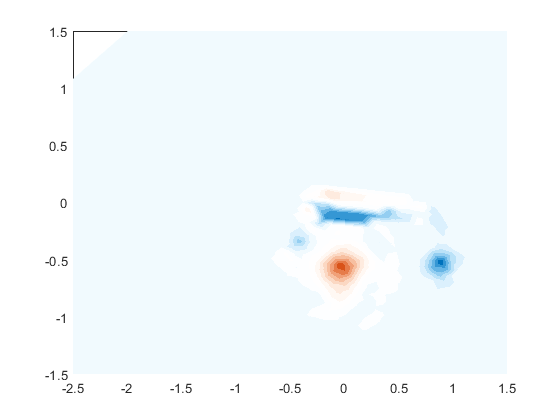

Bin = inpolygon(Xrot3,Yrot4,foiltest2(:,1),foiltest2(:,2));
curlz(Bin) = 0;
pcolor(Xrot3,Yrot4,curlz)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
shading interp
hold on
%fill(foiltest2(:,1),foiltest2(:,2)-2.042,'y')
hold off

[in,on] = inpolygon(Xrot3,Yrot4,foiltest2(:,1),foiltest2(:,2));
sum(sum(in+on))

ans = 19

[M,I] = min(curlz,[],"all")

M = -331.3884

I = 2551

Xrot3(I),Yrot4(I)

ans = 0.1278

ans = -4.0181

xl = [-2.5 1.5 1.5 -2.5 -2.5];
yl = [-1.5 -1.5 1.5 1.5 -1.5];
Din = inpolygon(Xrot3,Yrot4,xl,yl);
curlz(~Din) = 0;

ans =     0.0916
    0.0700
   -0.0042
    0.0089
   -0.0219
    0.0112
    0.0171
   -0.0143
    0.0164
    0.0395


Mxin = abs(curlz) > 70;
curlz(Mxin) = 0;

ans = 13

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

plot(xl,yl)
xlim([-3 2])
ylim([-2 2])

hypot((mean(u5(logical(Cin))))/Uinf,(mean(v5(logical(Cin))))/Uinf)

urelC = zeros(num,1);
urelP= urelC;
urelP2 = urelC;
AoAc = urelC;
AoAnom = AoAc;
AoAp = urelC;
AoAp1 = urelC;
for k = 1:num
alpha = theta(k);
bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
u5 = Us(k).u3+norm(bv);
v5 = Us(k).v3;
u1 = flow_data(k).u;
v1 = flow_data(k).v;
XY = [X(:) Y(:)];
Rot = [cosd(-alpha) sind(-alpha); -sind(-alpha) cosd(-alpha)];
res = XY*Rot;
% XYRy2 = XY*Ry2;
% res = subs(XYRy2,t,-alpha);
% res = double(res);
% deprecated bc I think it's slow
Xrot3 = reshape(res(:,1), size(X,1), []);
Yrot3 = reshape(res(:,2), size(Y,1), []);
Yrot4 = Yrot3-2.042;
[Cin,Ca] = Circle2([0;0],1,Xrot3,Yrot4);
[Pin,Pa] = Points2([0;0],1,0.5,Xrot3,Yrot4);
[Pin1,Pa1] = Points2([0;0],0.5,1,Xrot3,Yrot4);
urelP(k) = hypot((mean(u5(logical(Pin))))/Uinf,(mean(v5(logical(Pin))))/Uinf);
urelP2(k)= hypot((mean(u5(logical(Pin1))))/Uinf,(mean(v5(logical(Pin1))))/Uinf);
urelC(k) = hypot((mean(u5(logical(Cin))))/Uinf,(mean(v5(logical(Cin))))/Uinf);
[AoAc(k), AoAnom(k)] = AOA(bv,[(mean(u1(logical(Cin))))-bv(1);(mean(v1(logical(Cin))))-bv(2)],theta(k),GC);
AoAp(k) = AOA(bv,[(mean(u1(logical(Pin))))-bv(1);(mean(v1(logical(Pin))))-bv(2)],theta(k),GC);
AoAp1(k) = AOA(bv,[(mean(u1(logical(Pin1))))-bv(1);(mean(v1(logical(Pin1))))-bv(2)],theta(k),GC);
end

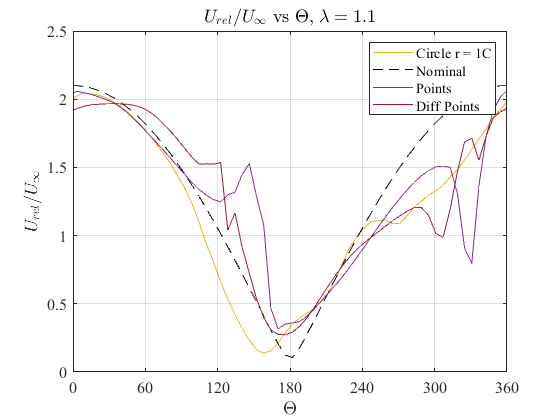

plot(theta(1:num),urelC,'Color','#EDB120')
hold on
plot(theta(1:num),sqrt(lam^2+2*lam*cosd(theta(1:num))+1),'k--')
plot(theta(1:num),urelP,'Color','#7E2F8E')
plot(theta(1:num),urelP2,'Color','#A2142F')
xlabel('$\Theta$','Interpreter','latex')
ylabel('$U_{rel}/U_\infty$','Interpreter','latex')
legend('Circle r = 1C','Nominal','Points','Diff Points')
set(gca,'layer','top','FontName','Times','FontSize',12)
title('$U_{rel}/U_\infty$ vs $\Theta$, $\lambda = 1.1$','Interpreter','latex')
xlim([0 360])
xticks([0 60 120 180 240 300 360])
grid on
set(gcf,'Visible','on','Color','w')
hold off

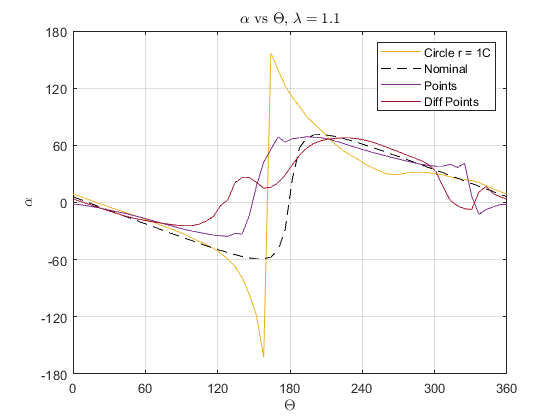

plot(theta(1:num),AoAc,'Color','#EDB120')
hold on
plot(theta(1:num),AoAnom,'k--')
plot(theta(1:num),AoAp,'Color','#7E2F8E')
plot(theta(1:num),AoAp1,'Color','#A2142F')
xlabel('$\Theta$','Interpreter','latex')
ylabel('$\alpha$','Interpreter','latex')
title('$\alpha$ vs $\Theta$, $\lambda = 1.1$','Interpreter','latex')
legend('Circle r = 1C','Nominal','Points','Diff Points')
xlim([0 360])
ylim([-180 180])
yticks([-180 -120 -60 0 60 120 180])
xticks([0 60 120 180 240 300 360])
grid on
hold off

AoAc = zeros(num,1);
AoAnom = AoAc;
AoAc2 = AoAc;
AoAnom2 = AoAc;
AoAp = AoAc;
XY = [X(:) Y(:)];
for k = 1:num
    alpha = theta(k);
    bv = Omega*rt.*[-cosd(alpha);-sind(alpha)];
    u5 = Us(k).u3+norm(bv);
    v5 = Us(k).v3;
    u1 = flow_data(k).u;
    v1 = flow_data(k).v;
    Rot = [cosd(-alpha) sind(-alpha); -sind(-alpha) cosd(-alpha)];
    res = XY*Rot;
    Xrot3 = reshape(res(:,1), size(X,1), []);
    Yrot3 = reshape(res(:,2), size(Y,1), []);
    Yrot4 = Yrot3-2.042;
    [Cin,Ca] = Circle2([0;0],1,Xrot3,Yrot4);
    [Pin,Pa] = Points2([0;0],1,0.5,Xrot3,Yrot4);
    [AoAc(k), AoAnom(k)] = AOA(bv,[(mean(u1(logical(Cin))))/Uinf;(mean(v1(logical(Cin))))/Uinf],theta(k),GC);
    AoAp(k) = AOA(bv,[(mean(u1(logical(Pin))))/Uinf;(mean(v1(logical(Pin))))/Uinf],theta(k),GC);
    [AoAc2(k), AoAnom2(k)] = AOA(bv,[(mean(u3(logical(Cin))))/Uinf;(mean(v3(logical(Cin))))/Uinf],theta(k),GC);
end
plot(theta(1:num),AoAc,theta(1:num),AoAnom,'k--',theta(1:num),AoAp)
plot(theta(1:num),AoAc2,theta(1:num),AoAnom2,'k--')

for k = 1:num
    alpha = theta(k);
    Rot = [cosd(-alpha) sind(-alpha); -sind(-alpha) cosd(-alpha)];
    res = XY*Rot;
    Xrot3 = reshape(res(:,1), size(X,1), []);
    Yrot3 = reshape(res(:,2), size(Y,1), []);
    Yrot4 = Yrot3-2.042;
    [Pin,Pa] = Points2([0;0],1,0.5,Xrot3,Yrot4);
    if sum(sum(Pin)) ~= 2
        'fail'
    end
end

vort = flow_data(k).vort;
vortRaw = griddedInterpolant(X,Y,vort)
vort2 = vortRaw(Xrot3,Yrot4);
vort3 = abs(vort2) > 70
vort2(vort3) = 0
f = figure
pcolor(Xrot3,Yrot4,vort2)
shading interp
% map = [1 0 0;1 1 1;0 0 1]
vec = [100;50;0];
raw = [0 0.4470 0.7410; 1 1 1;0.8500 0.3250 0.0980];
N = 16;
map = interp1(vec,raw,linspace(100,0,N),'pchip');
map = abs(map);
colormap(map)
colorbar
hold on
quiver(Xrot3,Yrot4,u5,v5)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
fill(foiltest2(:,1),foiltest2(:,2)-2.042,'y')
quiver(0,0,(mean(u5(logical(Pin))))/Uinf*Uinf,(mean(v5(logical(Pin))))/Uinf*Uinf,'LineWidth',2)
quiver(0,0,(mean(u5(logical(Cin))))/Uinf*Uinf,(mean(v5(logical(Cin))))/Uinf*Uinf,'LineWidth',2)
plot(Pa(1,:),Pa(2,:),'g*')
plot(Ca(:,1),Ca(:,2),'k')
grid on
set(gca,'layer','top','FontName','Times','FontSize',12)
xticks(-2.5:0.5:1.5)
yticks(-1.5:0.5:1.5)
xlabel('x/c')
ylabel('y/c')
title(strcat('$\theta$',sprintf(' = %.4f, oldVort',theta(k))),'Interpreter','latex')
hold off
set(gcf,'Visible','on','Color','w')
legend('','','','reference points','circle')

x = (mean(Us(k).u4(logical(Pin))))/Uinf;
y = (mean(Us(k).v4(logical(Pin))))/Uinf;
cart2pol(x,y)
x = (mean(Us(k).u4(logical(Pin)))+bv(1)*0)/Uinf*Uinf;
y = (mean(Us(k).v4(logical(Pin)))+bv(2)*0)/Uinf*Uinf;
cart2pol(x,y)
x = (mean(Us(k).u3(logical(Pin)))+bv(1))/Uinf*Uinf;
y = (mean(Us(k).v3(logical(Pin)))+bv(2))/Uinf*Uinf;
cart2pol(x,y)

Us(k).u4(logical(Pin))
X(logical(Pin))
Y(logical(Pin))
Us(k).u3(43,37)

cart2pol(0.25,-0.5)
cart2pol(0.4937,-1.3063)


norm(Urels(k).P)/Uinf